# NBAの勝敗と得失点を集計する

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

データを読み込む(prog_NBADataConcatenation.mlxを実行しておく)

load('../data/NBAResults.mat');

最新シーズンのレギュラーシーズンの順位表を作る

seasonStartYearVals=unique(tbl_teams.SeasonStartYear);
seasonStartYearVal=max(seasonStartYearVals)

seasonStartYearVal = 2018

ind = tbl_teams.SeasonStartYear==seasonStartYearVal;
tbl_teams_tmp=tbl_teams(ind,:);

ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
    & tbl_results.isRegular;
tbl_results_tmp=tbl_results(ind,:);

勝，負試合数，および得失点を集計する

集計用の変数を準備する

Wins=zeros(size(tbl_teams_tmp,1),1);
Loses=zeros(size(tbl_teams_tmp,1),1);
ScoresFor=zeros(size(tbl_teams_tmp,1),1);
ScoresAgainst=zeros(size(tbl_teams_tmp,1),1);

for n1=1:size(tbl_results_tmp,1)

それぞれの試合で両チームが何番に対応するかを見つける

    TeamANum=find(tbl_teams_tmp.TeamName==tbl_results_tmp.Home(n1));
    TeamBNum=find(tbl_teams_tmp.TeamName==tbl_results_tmp.Away(n1));

各チームの得失点を加える

    ScoresFor(TeamANum)=ScoresFor(TeamANum)+tbl_results_tmp.HomeScore(n1);
    ScoresFor(TeamBNum)=ScoresFor(TeamBNum)+tbl_results_tmp.AwayScore(n1);
    ScoresAgainst(TeamANum)=ScoresAgainst(TeamANum)+tbl_results_tmp.AwayScore(n1);
    ScoresAgainst(TeamBNum)=ScoresAgainst(TeamBNum)+tbl_results_tmp.HomeScore(n1);

得点の大小で場合分けし，勝・引分・負それぞれに加える

    if tbl_results_tmp.HomeScore(n1)>tbl_results_tmp.AwayScore(n1)
        Wins(TeamANum)=Wins(TeamANum)+1;
        Loses(TeamBNum)=Loses(TeamBNum)+1;
    elseif tbl_results_tmp.HomeScore(n1)<tbl_results_tmp.AwayScore(n1)
        Loses(TeamANum)=Loses(TeamANum)+1;
        Wins(TeamBNum)=Wins(TeamBNum)+1;
    end
end

勝率，得点割合の列を追加する

WinRatio=Wins./(Wins+Loses);
ScoreRatio=ScoresFor./(ScoresFor+ScoresAgainst);
tbl_teams_tmp=addvars(tbl_teams_tmp, WinRatio, ScoreRatio);

Divisionの順序をEastern, Westernそれぞれの順序とする

tbl_teams_tmp=sortrows(tbl_teams_tmp,{'Conference','Division'});

unique関数には「登場した順序を保持する」ことを指定するstableオプションがある．

divisionOrder=unique(tbl_teams_tmp.Division,'stable');

すでにカテゴリ型とした変数も順序付きのカテゴリ変数とできる．

tbl_teams_tmp.Division=categorical(tbl_teams_tmp.Division,divisionOrder,'Ordinal',true)

tbl_teams_tmp = 30×8 table
    SeasonStr    SeasonStartYear         TeamName          Conference    Division     Abb    WinRatio    ScoreRatio
    _________    _______________    ___________________    __________    _________    ___    ________    __________

    2018-2019         2018          Boston Celtics          Eastern      Atlantic     BOS    0.59756      0.51007  
    2018-2019         2018          Brooklyn Nets           Eastern      Atlantic     BKN     0.5122      0.49984  
    2018-2019         2018          New York Knicks         Eastern      Atlantic     NYK    0.20732      0.47892  
    2018-2019         2018          Philadelphia 76ers      Eastern      Atlantic     PHI    0.62195      0.50592  
    2018-2019         2018          Toronto Raptors         Eastern      Atlantic     TOR    0.70732      0.51366  
    2018-2019         2018          Chicago Bulls           Eastern      Central      CHI    0.26829      0.48073  
    2018-2019         2018          Clevelan

divisionOrder=categories(tbl_teams_tmp.Division)

divisionOrder = 6×1 の cell 配列
    {'Atlantic' }
    {'Central'  }
    {'Southeast'}
    {'Northwest'}
    {'Pacific'  }
    {'Southwest'}


散布図を描画する

figure;

マーカーの順序を用意する．

markerStyleStrs = 'o^sdv<';
markerStyleInd=1;
hold on;set(gca,'fontname','メイリオ');grid on;

Divisionごとにマーカを変えて散布図を描画する．

for divisionName=divisionOrder'
    ind = tbl_teams_tmp.Division==divisionName;
    scatter(tbl_teams_tmp.ScoreRatio(ind),tbl_teams_tmp.WinRatio(ind), ...
        markerStyleStrs(markerStyleInd), ...
        'linewidth',2);
    markerStyleInd=markerStyleInd+1;
end
xlabel('得失点割合');
ylabel('勝率');

最小二乗法の近似直線を追加する

a= pinv([tbl_teams_tmp.ScoreRatio ones(size(tbl_teams_tmp.ScoreRatio))]) ...
    *tbl_teams_tmp.WinRatio 

a =    13.0738
   -6.0366


plot([min(tbl_teams_tmp.ScoreRatio) max(tbl_teams_tmp.ScoreRatio)], ...
    [[min(tbl_teams_tmp.ScoreRatio) 1]*a, ...
    [max(tbl_teams_tmp.ScoreRatio) 1]*a ...
    ]);
legend(divisionOrder,'Location','southeast');

線形相関係数を算出する

corr(tbl_teams_tmp.ScoreRatio, tbl_teams_tmp.WinRatio)

ans = 0.9795

ケンドールの順位相関係数を算出する

corr(tbl_teams_tmp.ScoreRatio, tbl_teams_tmp.WinRatio,'type','Kendall')

ans = 0.8916

スピアマンの順位相関係数を算出する

corr(tbl_teams_tmp.ScoreRatio, tbl_teams_tmp.WinRatio,'type','Spearman')

ans = 0.9757

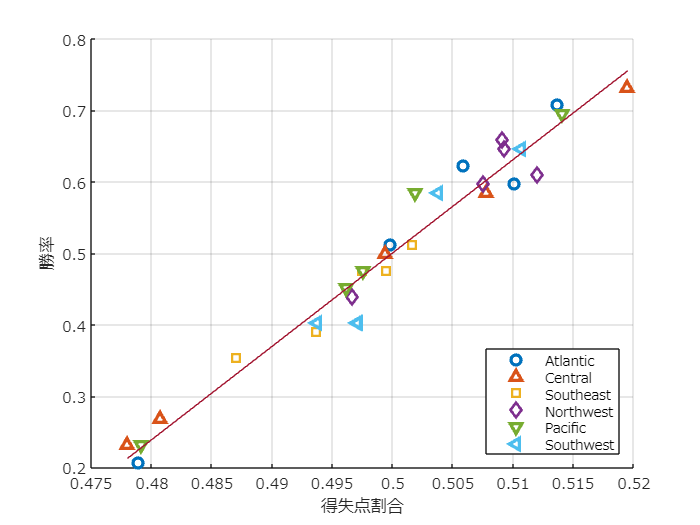

exportgraphics(gcf,'fig_NBAScoreRatioAndWinRatio.pdf');